clear
targetImage = im2double(imread("dogdogorange.png"));
targetImage = imresize(targetImage, 0.25);
load("M_XYZ2RGB.mat")
quantizeLevel = 30;
histColours = reshape(targetImage(1, 1, :),[3, 1]);
histColours(4,1) = 0;
[rMax, cMax, dMax] = size(targetImage);
for r = 1:rMax
    for c = 1:cMax
        [~, histLength] = size(histColours);
        currentColour = reshape(targetImage(r, c, :),[3, 1]);
        currentColourXYZ = inv(M_XYZ2RGB) * currentColour;
        currentColourXYZ = quantizeColour(currentColourXYZ, quantizeLevel);
        colourFound = false;
        for i = 1:histLength
            compareColour = reshape(histColours(1:3,i),[3, 1]);
            compareColourXYZ = inv(M_XYZ2RGB) * compareColour;
            compareColourXYZ = quantizeColour(compareColourXYZ, quantizeLevel);
            [meanDeltaE, Max] = calcDeltaE(currentColourXYZ', compareColourXYZ');
            
            % if same inc counter
            if meanDeltaE < quantizeLevel
                histColours(4,i) = histColours(4,i) + 1;
                colourFound = true;
                break
            end
        end
        % if we have not found the colour add it
        if colourFound == false
            histColours(1:3, end+1) = currentColour;
            histColours(4, end) = 1;
        end
    end
end

[~, histLength] = size(histColours);
histColours(4,:)

ans =        26922         865        1797        5627        1498         169          75        1150          76           8           4           1


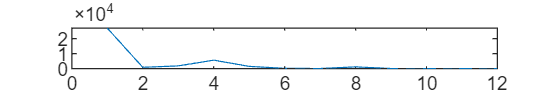

plot(histColours(4,:))

numberOfWantedColours = 10;
mostCommonColours = zeros(3, numberOfWantedColours);
for c = 1:numberOfWantedColours
    maxValue = 0;
    bestIndex = 1;
    for i = 1:histLength
        if histColours(4,i) > maxValue
            maxValue = histColours(4,i);
            bestIndex = i;
        end
    end
    histColours(4, bestIndex) = 0;
    mostCommonColours(:, c) = histColours(1:3, bestIndex);
end

mostCommonColours

mostCommonColours =     0.7193    0.2106    0.5899    0.4152    0.3298    0.5833    0.9704    0.2991    0.3053    0.0476
    0.6281    0.1888    0.6153    0.3640    0.3051    0.6001    0.9149    0.2872    0.3010    0.0017
    0.5512    0.1323    0.5860    0.2605    0.2437    0.5830    0.7655    0.2916    0.2842   -0.0061


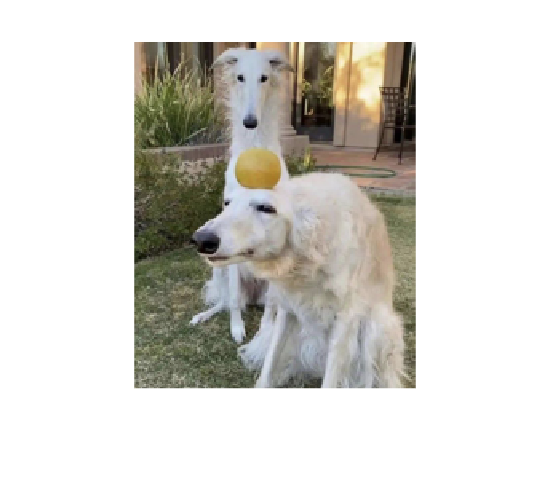

%histColours(1, :)
imshow(targetImage)

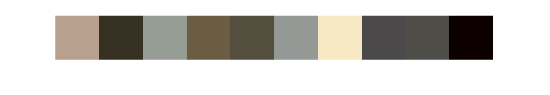

showRGB(mostCommonColours')

targetImage = im2double(imread("blue.png"));
colours = getImportantColours(targetImage, 5)

colours =     0.2471    0.2471    0.2471    0.2471    0.2471
    0.2824    0.2824    0.2824    0.2824    0.2824
    0.8000    0.8000    0.8000    0.8000    0.8000


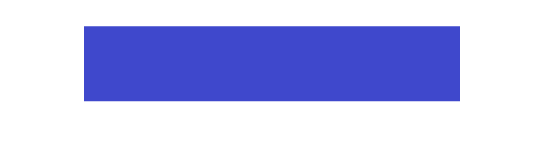

showRGB(colours')


compareImage = im2double(imread("blue2.png"));
colours2 = getImportantColours(compareImage, 5)

colours2 =     0.2471    0.5550    0.9343    0.7924    0.1360
    0.2824    1.0038    0.9560    0.9723    0.7429
    0.8000    0.9847    0.1426    0.4521    0.9607


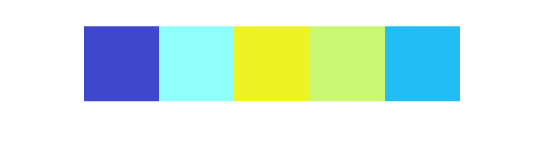

showRGB(colours2')

comparePrimaryColours(colours2, colours)

ans = logical
   1
